%test analysis of processivity etc
%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
motorPar.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorPar.pi0 =10*motorPar.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorPar.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration
%processivity is synthesis limited
motorPar.kOff0 = 10*motorPar.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)

motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.Nmax = 1;
motorPar.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here

motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
Nplus=dynamics.Nplus;
Nminus=dynamics.Nminus;
vCargo=dynamics.vCargo;



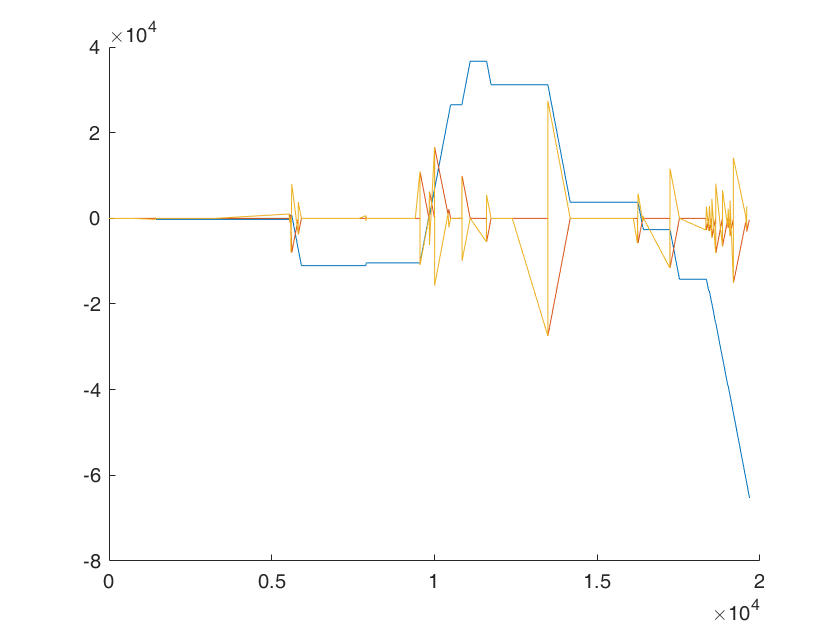

%find changes in dx,dt
dx=diff(x);
d2x=diff(dx);
ipt = findchangepts(x,'MaxNumChanges',numel(x));
tChgPt=t(ipt);
xChgPt=x(ipt);

figure;
hold all
plot(t,x);
plot(t(1:end-1),dx);
plot(t(1:end-2),d2x);

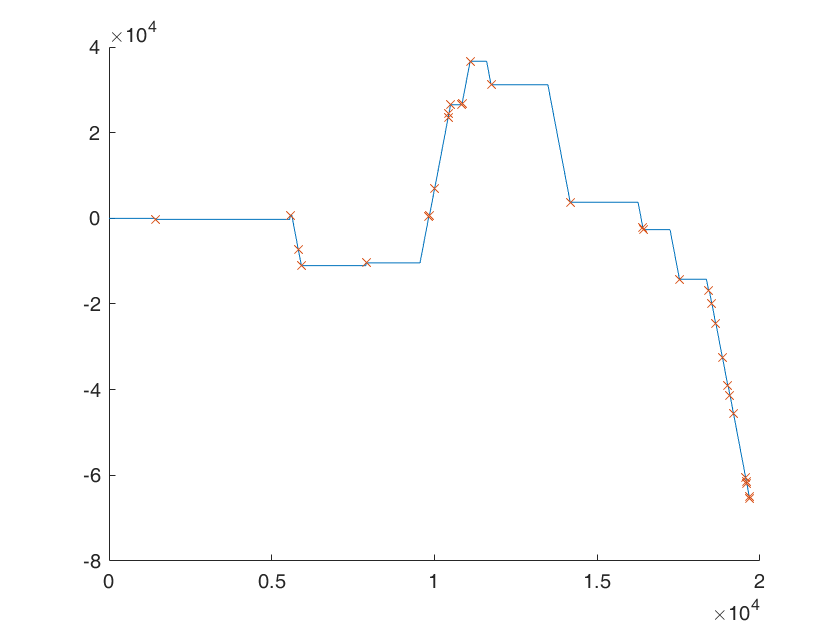

figure;
hold all
plot(t,x);
plot(tChgPt,xChgPt,'x')

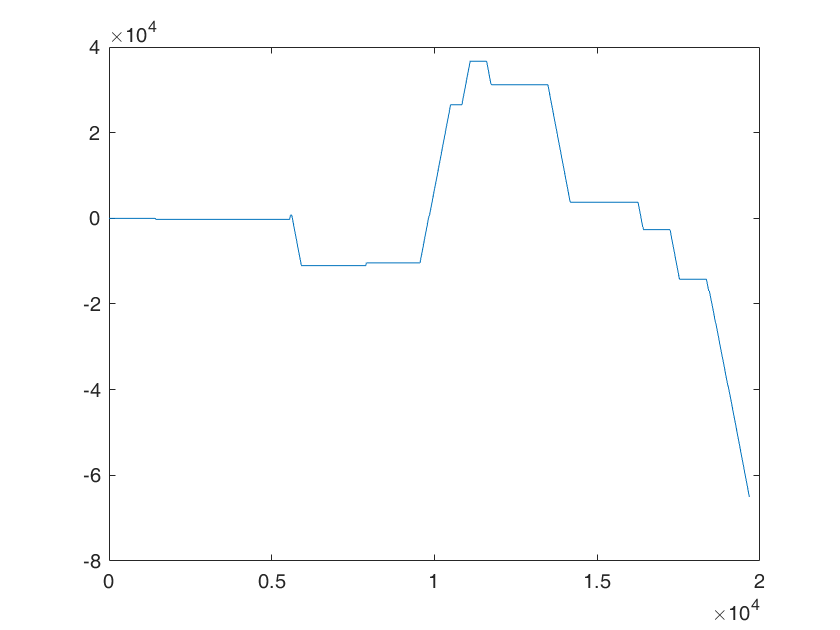


frameInterval= 6;%bin the data to the frame interval 
tFr = 0:6:max(t);
xFr = interp1(t,x,tFr);

figure;
plot(tFr,xFr);

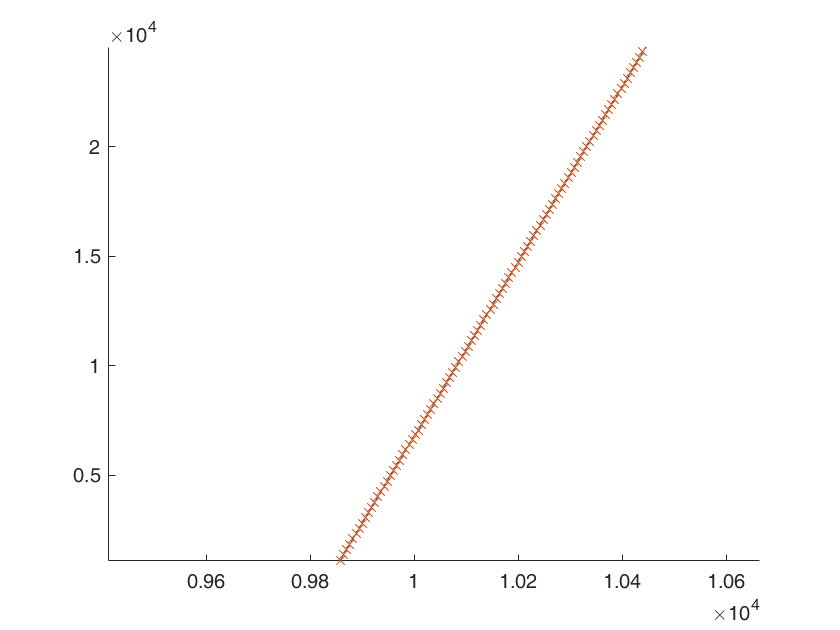


ipt = findchangepts(xFr,'MaxNumChanges',numel(xFr));
tChgPt=tFr(ipt);
xChgPt=xFr(ipt);
figure;
hold all
plot(t,x);
plot(tChgPt,xChgPt,'x')